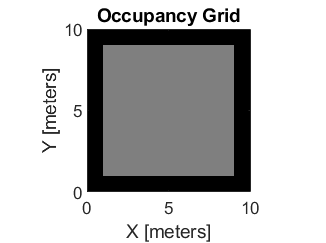

clear
clc

l = 10; %set length (# of rows) of grid map 
w = 10; %set width (# of columns) of grid map
%res = 2;  %define number of cells per meter for grid map ( sets resolution)


map = occupancyMap(l,w,"grid"); %generate grid map dimensions
n = zeros(map.GridSize(1), map.GridSize(2)); %generate array to store neural activity values

%set map boundaries
for x = 1:1:map.GridSize(1)
    setOccupancy(map,[1,x],1,"grid")
    setOccupancy(map,[x,1],1,"grid")
    setOccupancy(map,[map.GridSize(1),x],1,"grid")
    setOccupancy(map,[x,map.GridSize(2)],1,"grid") 
    
    pause(0.005)
    show(map)
end


mat = occupancyMatrix(map); %an array containing the actual values of each grid in the occupancy map

% clear 
% clc
% 
% env = zeros(20,20);

% map = occupancyMap(env);
% n = zeros(map.GridSize(1), map.GridSize(2)); %generate array to store neural activity values
% mat = occupancyMatrix(map); %an array containing the actual values of each grid in the occupancy map
% show(map)

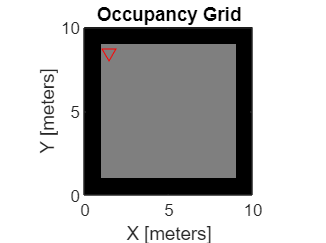

%initialize starting location
up = '^r'; %indicator for robot heading direction on map
down = 'vr'; %indicator for robot heading direction on map
left = '<r'; 
right = '>r';
hold on
startloc = [2,2]; %starting grid location
xy = grid2world(map,[startloc(1),startloc(2)]); %convert starting grid location to xy coordinates
plot(xy(1), xy(2), down) %plot starting location xy coordinates on map

pc = startloc; %initialize starting grid location as current position

%go = input('press 1 to advance... '); %manually simulating motion (for debugging purposes)



go = waitforbuttonpress; %CHANGEE!!!
while go == 1 
%for go = 1:500
%Building neural network of map
for j = 1:1:map.GridSize(2) %{Reference; j is cols (goes left to right)}
    for i = 1:1:map.GridSize(1)  %{Reference; i is rows (goes up and down)}
        ab = grid2world(map, [i,j]); %current grid position for neural activity calculation
        status = checkOccupancy(map, [ab(1),ab(2)]); %check status of current grid position
        %convert grid values to 'I' values
        if status == -1
            I = 100;
        elseif status == 0
            I = 0;
        else
            I = -100; 
        end
        I_plus = max([I 0]);
        I_neg = max([-1*I 0]);
        
        %check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
        try
            North = max([n(i-1, j) 0]); %North = max([n(i, j-1) 0]);
            dNorth = 0.7/((norm(ab - grid2world(map, [i-1, j])))); %dNorth = norm(ab - grid2world(map, [i, j-1]));
        catch
            North = 0;
            dNorth = 0;
        end 

        try
            South = max([n(i+1, j) 0]); %South = max([n(i, j+1) 0]);
            dSouth = 0.7/(norm(ab - grid2world(map, [i+1, j]))); %dSouth = norm(ab - grid2world(map, [i, j+1]));
        catch
            South = 0;
            dSouth = 0;
        end 

        try
            West = max([n(i, j-1) 0]); %West = max([n(i-1, j) 0]);   
            dWest  = 0.7/(norm(ab - grid2world(map, [i, j-1]))); %dWest  = norm(ab - grid2world(map, [i-1, j]));
        catch
            West = 0;
            dWest = 0;
        end 

        try
            East = max([n(i, j+1) 0]); %East = max([n(i+1, j) 0]);   
            dEast = 0.7/(norm(ab - grid2world(map, [i, j+1]))); %dEast = norm(ab - grid2world(map, [i+1, j]));
        catch
            East = 0;
            dEast = 0;
        end 

        try
            NW = max([n(i-1, j-1) 0]); %NW = max([n(i-1, j-1) 0]);
            dNW = 0.7/(norm(ab - grid2world(map, [i-1, j-1]))); %dNW = norm(ab - grid2world(map, [i-1, j-1]));
        catch
            NW = 0;
            dNW = 0;
        end 

        try
            NE = max([n(i-1, j+1) 0]); %NE = max([n(i+1, j-1) 0]);
            dNE = 0.7/(norm(ab - grid2world(map, [i-1, j+1]))); %dNE = norm(ab - grid2world(map, [i+1, j-1]));
        catch
            NE = 0;
            dNE = 0;
        end 

        try
            SW = max([n(i+1, j-1) 0]); %SW = max([n(i-1, j+1) 0]);
            dSW = 0.7/(norm(ab - grid2world(map, [i+1, j-1]))); %dSW = norm(ab - grid2world(map, [i-1, j+1]));
        catch
            SW = 0;
            dSW = 0;
        end 

        try
            SE = max([n(i+1, j+1) 0]); %SE = max([n(i+1, j+1) 0]);
            dSE = 0.7/(norm(ab - grid2world(map, [i+1, j+1]))); %dSE = norm(ab - grid2world(map, [i+1, j+1]));
        catch
            SE = 0;
            dSE = 0;
        end
        
        
        %store evaluated neural activity values for neighboring neurons (8x1 matrix/array)
        xplus = [North, South, West, East, NW, NE, SW, SE];
        
        %store euclidean distances (1x8 matrix/array)
        wij = [dNorth; dSouth; dWest; dEast; dNW; dNE; dSW; dSE];
        
        %calculate the weight
        weight = xplus * wij; % Matrix operation calculating for the weight (order of operation should not be changed)
        
        %set variables
        A = 80;
        B = 1;
        D = 1;
        %define & evaluate equation using ODE solver 
        eqn = @(t,Xi) ((-A*Xi) + (B-Xi)*(I_plus + weight) - (D+Xi)*I_neg);
        [t,Xi] = ode45(eqn, [0:1], n(i,j));
        n(i,j) = Xi(end);
%         if Xi(end) < 0
%             n(i,j) = -0.6;%min(Xi);
%         elseif Xi(end) > 0.6
%             n(i,j) = 0.6;%max(Xi);
%         elseif (Xi(end) > 0) && (Xi(end) < 0.6)  
%             n(i,j) = 0;%min(Xi);
%         end
    end
end

%mesh(n)



if pc == startloc %if current position eqauls starting position
    gpc = grid2world(map, pc); %convert current location grid index to global xy values
    pp = [1,2]; %set previous position 
    gpp = grid2world(map, pp); %convert previous location grid index to global xy values

    %Find all possible next positions 
    pjN = grid2world(map, [pc(1)-1, pc(2)]); %North as the next position 
    pjS = grid2world(map, [pc(1)+1, pc(2)]); %South as the next position 
    pjW = grid2world(map, [pc(1), pc(2)-1]); %West as the next position 
    pjE = grid2world(map, [pc(1), pc(2)+1]); %East as the next position 
    pjNW = grid2world(map, [pc(1)-1, pc(2)-1]); %NW as the next position 
    pjNE = grid2world(map, [pc(1)-1, pc(2)+1]); %NE as the next position 
    pjSW = grid2world(map, [pc(1)+1, pc(2)-1]); %SW as the next position 
    pjSE = grid2world(map, [pc(1)+1, pc(2)+1]); %SE as the next position 
    
    %Evaluate for next position
    %next - current, current - previous
    %|atan2(ypj − ypc ,xpj −xpc ) − atan2(ypc − ypp ,xpc − xpp )|
    c = 0.5;

    r = abs(atan2(pjN(2)-xy(2),pjN(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjN = ((1 - (r/pi)));
    kN = n(pc(1)-1, pc(2)) + c*yjN; 
    
    r1 = abs(atan2(pjS(2)-xy(2),pjS(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjS = ((1 - (r1/pi)));
    kS = n(pc(1)+1, pc(2)) + c*yjS;
    
    r2 = abs(atan2(pjW(2)-xy(2),pjW(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjW = ((1 - (r2/pi)));
    kW = n(pc(1), pc(2)-1) + c*yjW;
    
    r3 = abs(atan2(pjE(2)-xy(2),pjE(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjE = ((1 - (r3/pi)));
    kE = n(pc(1), pc(2)+1) + c*yjE;
    
    r4 = abs(atan2(pjNW(2)-xy(2),pjNW(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjNW = ((1 - (r4/pi)));
    kNW = n(pc(1)-1, pc(2)-1) + c*yjNW;
    
    r5 = abs(atan2(pjNE(2)-xy(2),pjNE(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjNE = ((1 - (r5/pi)));
    kNE = n(pc(1)-1, pc(2)+1) + c*yjNE;
    
    r6 = abs(atan2(pjSW(2)-xy(2),pjSW(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjSW = ((1 - (r6/pi)));
    kSW = n(pc(1)+1, pc(2)-1) + c*yjSW;
    
    r7 = abs(atan2(pjSE(2)-xy(2),pjSE(1)-xy(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjSE = ((1 - (r7/pi)));
    kSE = n(pc(1)+1, pc(2)+1) + c*yjSE;
    
    pn = [kN,kS,kW,kE,kNW,kNE,kSW,kSE]; %do not change the order of this array!!!
    setOccupancy(map,gpc,0)
    show(map)
    pp = pc;
    gpp = grid2world(map, pp);
    switch max(pn)
        case pn(1)
            pc = [pc(1)-1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('north is next')
            plot(gpc(1), gpc(2),up)
        case pn(2)
            pc = [pc(1)+1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('south is next')
            plot(gpc(1), gpc(2),down)
        case pn(3)
            pc = [pc(1), pc(2)-1];
            gpc = grid2world(map, pc);
            %disp('west is next')
            plot(gpc(1), gpc(2),left)
        case pn(4)
            pc = [pc(1), pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('east is next')
            plot(gpc(1), gpc(2),right)
        case pn(5)
            pc = [pc(1)-1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('nw is next')
            plot(gpc(1), gpc(2),up)
        case pn(6)
            pc = [pc(1)-1, pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('ne is next')
            plot(gpc(1), gpc(2),up)
        case pn(7)
            pc = [pc(1)+1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('sw is next')
            plot(gpc(1), gpc(2),down)
        case pn(8)
            pc = [pc(1)+1, pc(2)+1];
            gpc = grid2world(map, pc);
            %disp('se is next')
            plot(gpc(1), gpc(2),down)
    end

    %pc = pn;
    %gpc = grid2world(map, pc);
else
    %Find all possible next positions 
    pjN = grid2world(map, [pc(1)-1, pc(2)]); %North as the next position 
    pjS = grid2world(map, [pc(1)+1, pc(2)]); %South as the next position 
    pjW = grid2world(map, [pc(1), pc(2)-1]); %West as the next position 
    pjE = grid2world(map, [pc(1), pc(2)+1]); %East as the next position 
    pjNW = grid2world(map, [pc(1)-1, pc(2)-1]); %NW as the next position 
    pjNE = grid2world(map, [pc(1)-1, pc(2)+1]); %NE as the next position 
    pjSW = grid2world(map, [pc(1)+1, pc(2)-1]); %SW as the next position 
    pjSE = grid2world(map, [pc(1)+1, pc(2)+1]); %SE as the next position
   
    %Evaluate for next position
    %next - current, current - previous
    %|atan2(ypj − ypc ,xpj −xpc ) − atan2(ypc − ypp ,xpc − xpp )|

    r = abs(atan2(pjN(2)-gpc(2),pjN(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjN = ((1 - (r/pi)));
    kN = n(pc(1)-1, pc(2)) + c*yjN;
    
    r1 = abs(atan2(pjS(2)-gpc(2),pjS(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjS = ((1 - (r1/pi)));
    kS = n(pc(1)+1, pc(2)) + c*yjS;
    
    r2 = abs(atan2(pjW(2)-gpc(2),pjW(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjW = ((1 - (r2/pi)));
    kW = n(pc(1), pc(2)-1) + c*yjW;
    
    r3 = abs(atan2(pjE(2)-gpc(2),pjE(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjE = ((1 - (r3/pi)));
    kE = n(pc(1), pc(2)+1) + c*yjE;
    
    r4 = abs(atan2(pjNW(2)-gpc(2),pjNW(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjNW = ((1 - (r4/pi)));
    kNW = n(pc(1)-1, pc(2)-1) + c*yjNW;
    
    r5 = abs(atan2(pjNE(2)-gpc(2),pjNE(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjNE = ((1 - (r5/pi)));
    kNE = n(pc(1)-1, pc(2)+1) + c*yjNE;
    
    r6 = abs(atan2(pjSW(2)-gpc(2),pjSW(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjSW = ((1 - (r6/pi)));
    kSW = n(pc(1)+1, pc(2)-1) + c*yjSW;
    
    r7 = abs(atan2(pjSE(2)-gpc(2),pjSE(1)-gpc(1)) - atan2(gpc(2)-gpp(2),gpc(1)-gpp(1)));
    yjSE = ((1 - (r7/pi)));
    kSE = n(pc(1)+1, pc(2)+1) + c*yjSE;

    pn = [kN,kS,kW,kE,kNW,kNE,kSW,kSE]; %do not change the order of this array!!!

    pp = pc;
    gpp = grid2world(map, pp);
    setOccupancy(map,gpp,0)
    pause(0.005)
    show(map)

    switch max(pn)
        case pn(1)
            pc = [pc(1)-1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('north is next')
            plot(gpc(1), gpc(2),up)
        case pn(2)
            pc = [pc(1)+1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('south is next')
            plot(gpc(1), gpc(2),down)
        case pn(3) 
            pc = [pc(1), pc(2)-1];
            gpc = grid2world(map, pc);
            %disp('west is next')
            plot(gpc(1), gpc(2),left)
            
%             if n(pc(1)-1, pc(2)) ~= -0.6  %check if north is not obstacle
%                 %update map
%                 pp = pc;
%                 gpp = grid2world(map, pp);
%                 setOccupancy(map,gpp,0)
%                 pause(0.005)
%                 show(map)
%                 %move north if not obstacle
%                 pc = [pc(1)-1, pc(2)];
%                 gpc = grid2world(map, pc);
%                 %disp('north is next')
%                 plot(gpc(1), gpc(2),up)
% 
%             elseif n(pc(1)+1, pc(2)) ~= -0.6 %check if south is not obstacle
%                 %update map
%                 pp = pc;
%                 gpp = grid2world(map, pp);
%                 setOccupancy(map,gpp,0)
%                 pause(0.005)
%                 show(map)
%                 %move south if not obstacle 
%                 pc = [pc(1)+1, pc(2)];
%                 gpc = grid2world(map, pc);
%                 %disp('north is next')
%                 plot(gpc(1), gpc(2),up)
%         
%             else %else continue with next path
%                 pause(0.005)
%             end 
                         
        case pn(4)
            pc = [pc(1), pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('east is next')
            plot(gpc(1), gpc(2),right)

%              if n(pc(1)-1, pc(2)) ~= -0.6  %check if north is not obstacle
%                 %update map
%                 pp = pc;
%                 gpp = grid2world(map, pp);
%                 setOccupancy(map,gpp,0)
%                 pause(0.005)
%                 show(map)
%                 %move north if not obstacle
%                 pc = [pc(1)-1, pc(2)];
%                 gpc = grid2world(map, pc);
%                 %disp('north is next')
%                 plot(gpc(1), gpc(2),up)
% 
%             elseif n(pc(1)+1, pc(2)) ~= -0.6 %check if south is not obstacle
%                 %update map
%                 pp = pc;
%                 gpp = grid2world(map, pp);
%                 setOccupancy(map,gpp,0)
%                 pause(0.005)
%                 show(map)
%                 %move south if not obstacle 
%                 pc = [pc(1)+1, pc(2)];
%                 gpc = grid2world(map, pc);
%                 %disp('north is next')
%                 plot(gpc(1), gpc(2),up)
%                 %move north if not occupied
% 
%             else
%                 pause(0.005)
%              end

        case pn(5)
            pc = [pc(1)-1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('nw is next')
            plot(gpc(1), gpc(2),up)
        case pn(6)
            pc = [pc(1)-1, pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('ne is next')
            plot(gpc(1), gpc(2),up)
        case pn(7)
            pc = [pc(1)+1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('sw is next')
            plot(gpc(1), gpc(2),down)
        case pn(8)
            pc = [pc(1)+1, pc(2)+1];
            gpc = grid2world(map, pc);
            %disp('se is next')
            plot(gpc(1), gpc(2),down)
    end
end

mat = occupancyMatrix(map); %update grid values of the map 
%mesh(n)
% Stop condition 
check = find(n >= 0.5);
if isempty(check) == 1
    go = 0;
end 

end